# Power Method and Rayleigh Quotient to approximate eigenvectors/eigenvalues

Power Method (power iteration) algorithm for any square matrix $A$:

- Start with any non-zero vector $x_{\left(0\right)}$ and divide by its length to make it a unit vector.

- For $k\ge 1,{\;x}_{\left(k\right)} =Ax_{\left(k-1\right)}$. Alternatively, $x_{\left(k\right)} =A^k x_{\left(0\right)} \ldotp$

- Normalizing the previous formula yields: $x_{\left(k\right)} =\frac{Ax_{\left(k-1\right)} }{\left\|Ax_{\left(k-1\right)} \right\|}$.

Rayleigh Quotient for any unit vector $x$ ($\left\|x\right\|=1$) and any square matrix $A$:

- $R\left(A,x\right)=x^T \textrm{Ax}$. 

Now, let's see how these two concepts work in practice. Let's start by generating a random 2x2 matrix $A$ and a random non-zero vector $x_{\left(0\right)}$. Check MathWorks documentation pages for [randi](https://www.mathworks.com/help/matlab/ref/randi.html).

A=randi(3,2,2)

A =      3     1
     3     3


x0=randi(3,2,1)

x0 =      2
     1


We will now normalize vector $x_{\left(0\right)}$ to be a unit vector. Check [norm](https://www.mathworks.com/help/matlab/ref/norm.html) command.

x0=x0/norm(x0)

x0 =     0.8944
    0.4472


We'll now create a loop that implements the power method. Check doc page for [while](https://www.mathworks.com/help/matlab/ref/while.html). We'll run the iteration 5 times. You can do the same with a [for](https://www.mathworks.com/help/matlab/ref/for.html) loop. A while loop simply allows us to run the iteration until a certain condition is met. This will come in handy in one of your assignments (hint).

n=1;
x=x0;
while n<6
    x=(A*x)/norm(A*x);
n=n+1;
end
x

x =     0.5006
    0.8657


Let's first visualize the power method outcome. We'll plot the inital vector $x_{\left(0\right)}$ versus $Ax_{\left(0\right)}$. Check the [quiver](https://www.mathworks.com/help/matlab/ref/quiver.html), [hold](https://www.mathworks.com/help/matlab/ref/hold.html) and [legend](https://www.mathworks.com/help/matlab/creating_plots/add-legend-to-graph.html) commands.

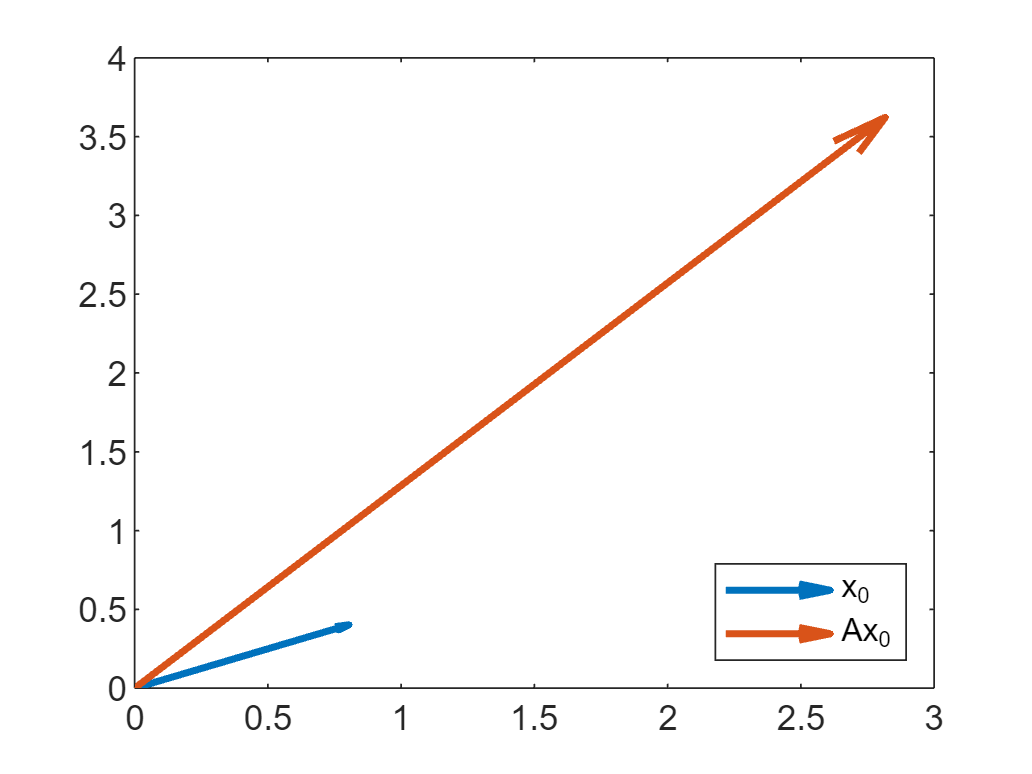

Ax0=A*x0;
quiver(0,0,x0(1,1),x0(2,1),'LineWidth',2)
hold on
quiver(0,0,Ax0(1,1),Ax0(2,1),'LineWidth',2)
legend('x_0','Ax_0','Location','southeast')
hold off

We'll now plot the resulting vector $x$ or in this case $x_{\left(5\right)}$ versus $Ax_{\left(5\right)}$. 

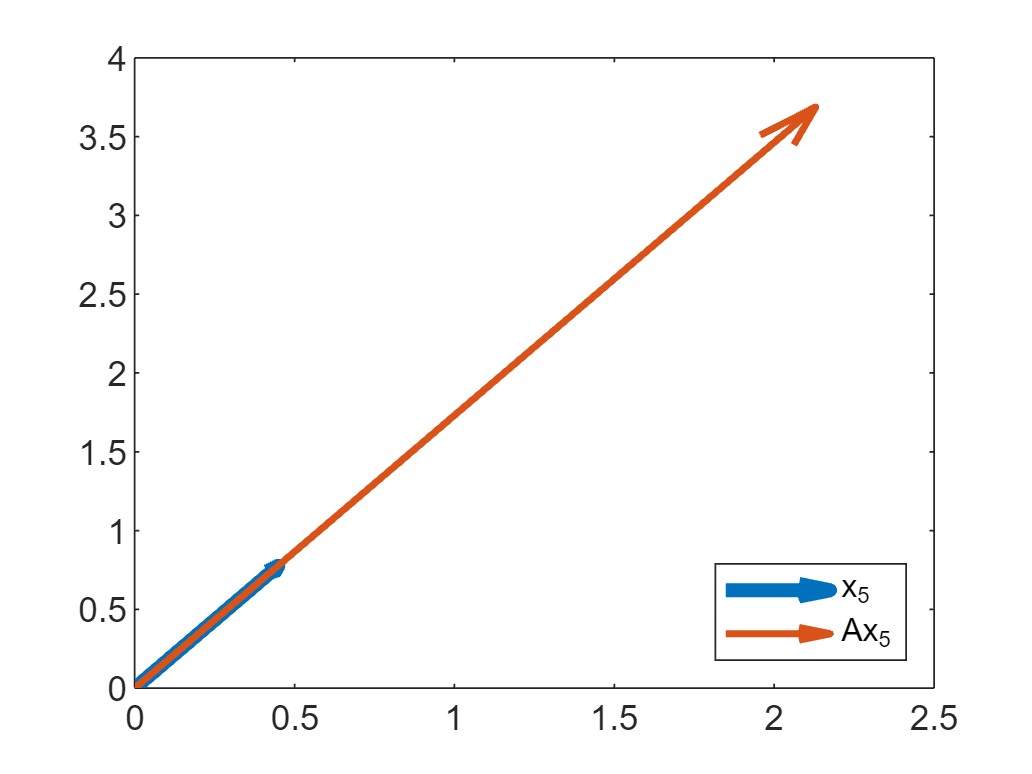

Ax=A*x;
quiver(0,0,x(1,1),x(2,1),'LineWidth',4)
hold on
quiver(0,0,Ax(1,1),Ax(2,1),'LineWidth',2)
legend('x_5','Ax_5','Location','southeast')
hold off

Notice anything by comparing the two plots? So what did the power iteration do? Anything you can say about vector $x_{\left(5\right)}$? Let's check by using the [eig](https://www.mathworks.com/help/matlab/ref/eig.html) command in MATLAB.

[v,d]=eig(A);
v

v =     0.5000   -0.5000
    0.8660    0.8660


x

x =     0.5006
    0.8657


Now let's calculate the Rayleigh quotient for $x_{\left(5\right)}$ and display that alongside the eigenvalues of $A$. Check [transpose](https://www.mathworks.com/help/matlab/ref/transpose.html) command in MATLAB.

rayleigh=transpose(x)*A*x

rayleigh = 4.7334

d

d =     4.7321         0
         0    1.2679


The Rayleigh quotient is a great way to calculate dominant eigenvalues if vector $x$ is an eigenvector of $A$. And by using the power iteration, we are guaranteed to find a dominant eigenvector.

So we just discovered an alternative way of calculating eigenvalues/eigenvectors for any given square matrix. The caveat here is that we can't calculate all the eigenvalues but only the dominant (largest/smallest) ones. This may sound like a major limitation but for most engineering and real-life problems it is more than enough. You can read more about applications of dominant eigenvalues in mechanical engineering in [this paper](https://pubs.sciepub.com/ajme/6/3/3/index.html).

But are there other, computational reasons why we shouldn't use the characteristic polynomial to calculate eigenvalues? Let's see. We'll compare calculation speed of power iteration versus the characteristic polynomial approach for a random 6x6 matrix. First, let's see how fast power iteration is. Check [rand](https://www.mathworks.com/help/matlab/ref/rand.html) and [tic](https://www.mathworks.com/help/matlab/ref/tic.html) functions.

A=rand(6);
x0=rand(6,1);
x0=x0/norm(x0);
n=1;
x=x0;
tic
while n<6
    x=(A*x)/norm(A*x);
n=n+1;
end
rayleigh=transpose(x)*A*x;
time1=toc

time1 = 0.0160

[v,d]=eig(A)

v =    0.4622 + 0.0000i   0.2595 + 0.1777i   0.2595 - 0.1777i   0.3852 + 0.0000i  -0.0225 + 0.0000i   0.0521 + 0.0000i
   0.3618 + 0.0000i  -0.3015 + 0.3002i  -0.3015 - 0.3002i  -0.1607 + 0.0000i   0.2826 + 0.0000i  -0.7825 + 0.0000i
   0.5200 + 0.0000i  -0.1815 - 0.3566i  -0.1815 + 0.3566i   0.4562 + 0.0000i  -0.3340 + 0.0000i   0.1435 + 0.0000i
   0.1810 + 0.0000i  -0.0409 - 0.2904i  -0.0409 + 0.2904i  -0.3241 + 0.0000i   0.6542 + 0.0000i   0.0641 + 0.0000i
   0.3041 + 0.0000i  -0.2915 + 0.3113i  -0.2915 - 0.3113i   0.1747 + 0.0000i  -0.0343 + 0.0000i   0.5088 + 0.0000i
   0.5098 + 0.0000i   0.5404 + 0.0000i   0.5404 + 0.0000i  -0.6944 + 0.0000i  -0.6156 + 0.0000i   0.3184 + 0.0000i


d =    3.4159 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.4340 + 0.5940i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.4340 - 0.5940i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.6859 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3673 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0612 + 0.0000i


x

x =     0.4622
    0.3619
    0.5200
    0.1810
    0.3042
    0.5097


rayleigh

rayleigh = 3.4160

Now let's derive the eigenvalues using the characteristic polynomial. Check [syms](https://www.mathworks.com/help/symbolic/syms.html), [charpoly](https://www.mathworks.com/help/symbolic/sym.charpoly.html), [solve](https://www.mathworks.com/help/symbolic/sym.solve.html) and [vpa](https://www.mathworks.com/help/symbolic/vpa.html) functions. VPA is used to numerically approximate the symbolic output of the solution.

tic
syms x
charpol = charpoly(A,x);
eigenvalues = vpa(solve(charpol),4)

$$eigenvalues = \left(\begin{array}{c} 0.06123\\ 0.3673\\ -0.6859\\ -0.434+0.594\,\mathrm{i}\\ -0.434-0.594\,\mathrm{i}\\ 3.416 \end{array}\right)$$

time2=toc

time2 = 0.6937

You can see that the power iteration runs much faster than the characteristic polynomial alternative. And this is only with a 6x6 matrix. As the dimension of matrix $A$ increases, eigenvalue calculation time using the characteristic polynomial approach rises significantly.

But this is just one of the problems. Finding eigenvalues by calculating the characteristic polynomial comes down to finding roots. And polynomial roots can be very sensitive to perturbations (minor changes) in the polynomial coefficients. In real-life applications, it often happens that we don't have 100% accurate parameter estimation and this practically translates to some inaccuracies in the characteristic polynomial coefficients. Therefore, the characteristic polynomial is not very reliable if we want to approximate eigenvalues in a practical scenario.

MathWorks' chief mathematician and co-founder, Cleve Moler, wrote about this in his blog 11 years ago: [Cleve's Corner: Wilkinson's Polynomials](https://blogs.mathworks.com/cleve/2013/03/04/wilkinsons-polynomials/). It's an interesting read if you have the time but don't go too deep. Specifically in the Wilkinson's perturbation section he talks about what happens if we change one polynomial coefficient by a tiny little bit ($2^{-k} ,23\le k\le 36$). And by the way, that blog is also a MATLAB Livescript (what you are currently reading).

## **Assignments**

- Create a MATLAB function that implements the power iteration for any given matrix and terminates when $\left|R\left(A,x_{\left(k\right)} \right)-R\left(A,x_{\left(k-1\right)} \right)\right|\le \varepsilon R\left(A,x_{\left(k\right)} \right)$ and $\left\|x_{\left(k\right)} -x_{\left(k-1\right)} \right\|\le \varepsilon$ for an arbitrarily small $\varepsilon$ of your choice. Test for different matrices and multiple values for $\varepsilon$ and confirm it's working properly by displaying and comparing the results with the eig function. How many iterations do we need for the algorithm to converge for each matrix?

- Run the function you created before for the inverse of a random matrix $A^{-1}$. What do you notice? Support your claims with numerical results.

Check documentation pages for [function](https://www.mathworks.com/help/matlab/ref/function.html), [abs](https://www.mathworks.com/help/matlab/ref/abs.html), [if](https://www.mathworks.com/help/matlab/ref/if.html) and [inv](https://www.mathworks.com/help/matlab/ref/inv.html). 